% Import data from text file
data8 = readtable("M:\Documents\MATLAB\csv_files\SDS00008.csv");

% Display results
data8

data8 = 70000×3 table
    Source     CH1     CH2 
    ______    _____    ____

        0     -0.04    0.02
    0.001     -0.04    0.04
    0.002     -0.06    0.06
    0.003     -0.06     0.1
    0.004      -0.1    0.14
    0.005     -0.12    0.14
    0.006     -0.08    0.18
    0.007      -0.1    0.16
    0.008      -0.1    0.16
    0.009      -0.1    0.14
     0.01      -0.1    0.12
    0.011      -0.1     0.1
    0.012      -0.1    0.06
    0.013      -0.1    0.06
    0.014     -0.08    0.02
    0.015     -0.06       0


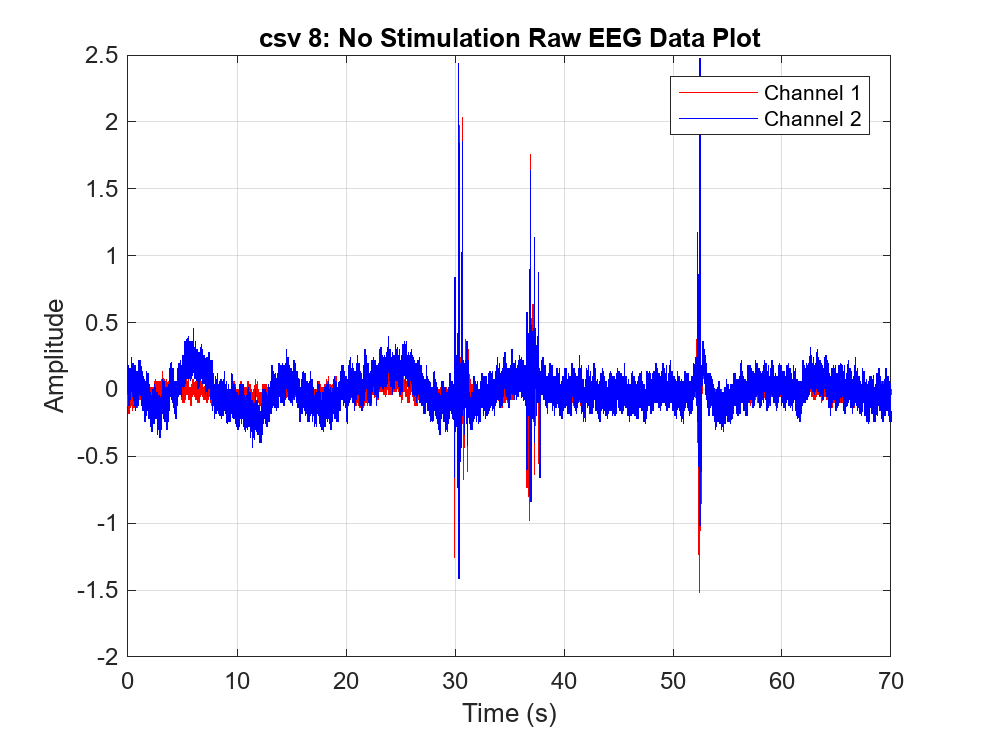

time = data8.Source; % 'Source' is the time column
channel1 = data8.CH1;
channel2 = data8.CH2;

% Plot the data
figure;
plot(time, channel1, 'r', 'DisplayName', 'Channel 1'); 
hold on; 
plot(time, channel2, 'b', 'DisplayName', 'Channel 2'); 
hold off;

% Add labels and legend
xlabel('Time (s)');
ylabel('Amplitude');
title('csv 8: No Stimulation Raw EEG Data Plot');
legend show;
grid on;

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\akatikhaneni\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.5 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.04' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "erplab" v10.04 (see >> help eegplugin_erplab) - new version 12.00 available
EEGLAB: addin

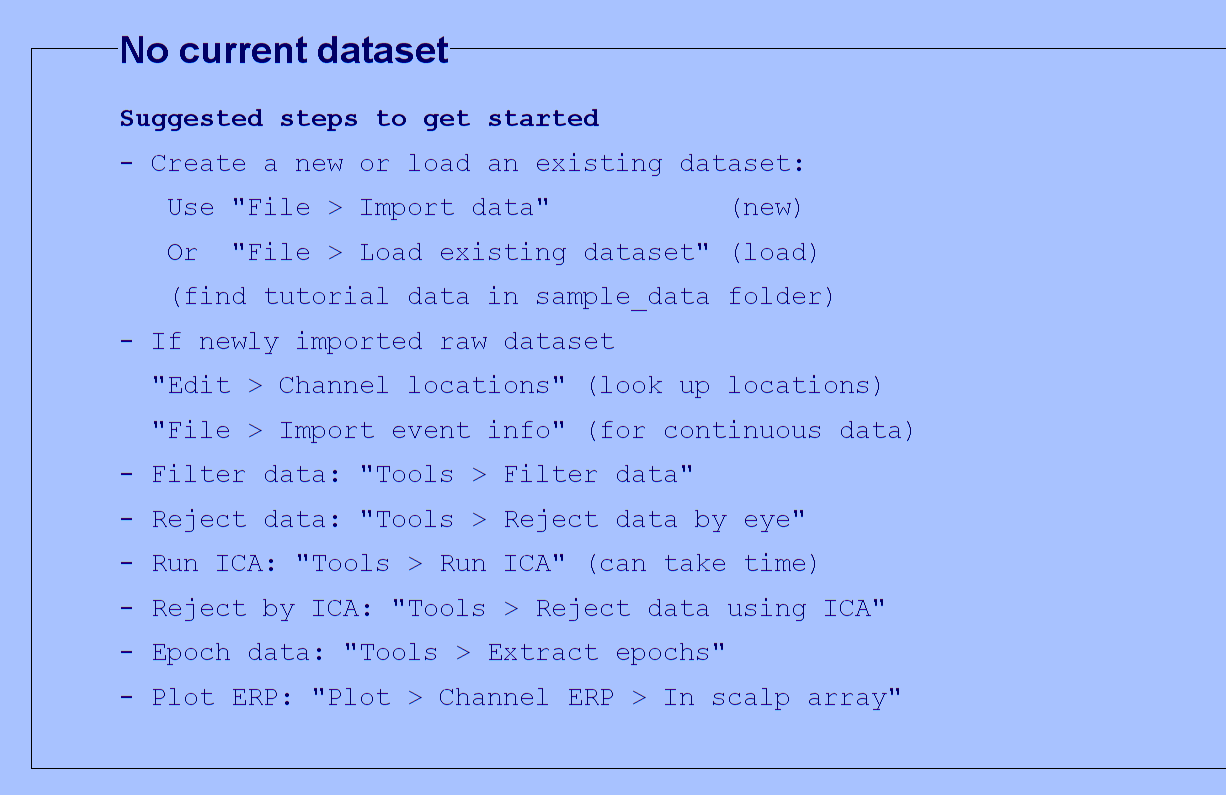


raw_data = table2array(data8(:, 2:end)); 

time = data8.Source;

eeglab;


fs = 1000; 

EEG = pop_importdata('setname', 'csv 8 Raw EEG Data', ... 
                     'data', raw_data', ...         % transpose to [time points x channels]
                     'srate', fs, ...              
                     'nbchan', size(raw_data, 2), ... 
                     'xmin', time(1));             

eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (70000) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



chan_labels = {'CH1', 'CH2'};
for i = 1:length(chan_labels)
    EEG.chanlocs(i).labels = chan_labels{i};
end

pop_saveset(EEG, 'filename', 'csv8_raw_eeg.set', 'filepath', './');

Saving dataset...


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


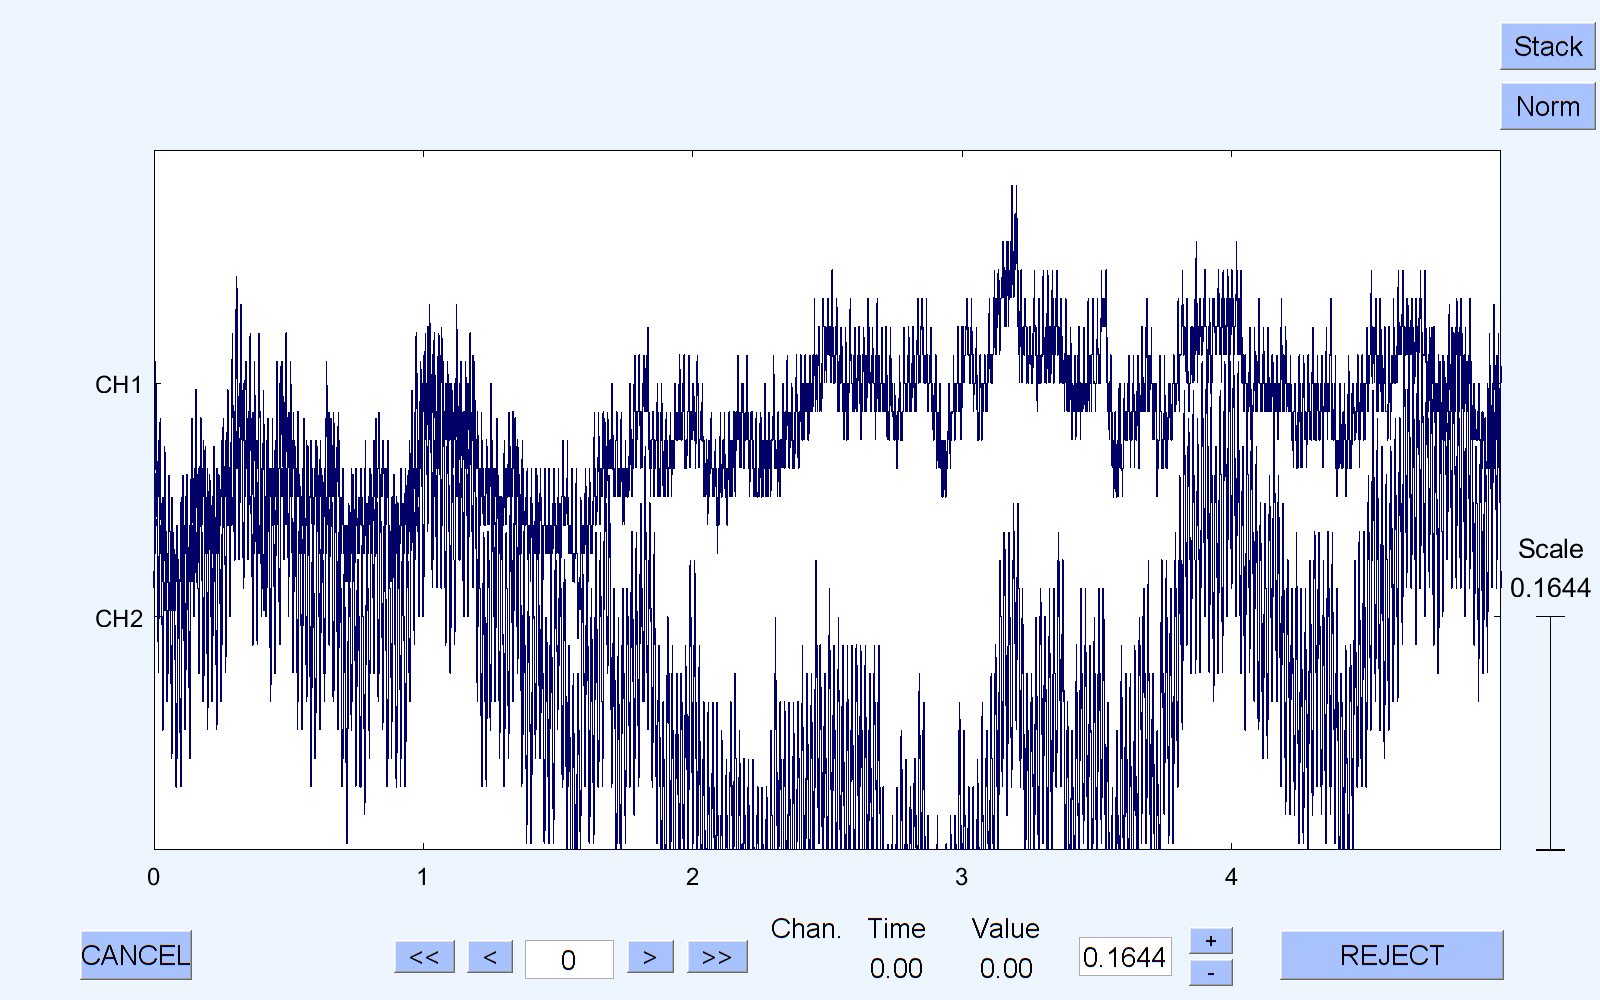


pop_eegplot(EEG);

whisker_data = readtable("M:\Documents\MATLAB\csv_files\SDS00010.csv")

whisker_data = 70000×3 table
    Source     CH1      CH2 
    ______    _____    _____

        0     -0.02    -0.06
    0.001     -0.02    -0.02
    0.002     -0.02    -0.02
    0.003     -0.02     0.04
    0.004     -0.04     0.08
    0.005     -0.04     0.12
    0.006     -0.04     0.14
    0.007         0     0.16
    0.008     -0.02     0.16
    0.009     -0.02     0.16
     0.01     -0.02     0.14
    0.011         0      0.1
    0.012     -0.04     0.08
    0.013     -0.04     0.06
    0.014     -0.04     0.04
    0.015     -0.04        0



whisker_data

whisker_data = 70000×3 table
    Source     CH1      CH2 
    ______    _____    _____

        0     -0.02    -0.06
    0.001     -0.02    -0.02
    0.002     -0.02    -0.02
    0.003     -0.02     0.04
    0.004     -0.04     0.08
    0.005     -0.04     0.12
    0.006     -0.04     0.14
    0.007         0     0.16
    0.008     -0.02     0.16
    0.009     -0.02     0.16
     0.01     -0.02     0.14
    0.011         0      0.1
    0.012     -0.04     0.08
    0.013     -0.04     0.06
    0.014     -0.04     0.04
    0.015     -0.04        0


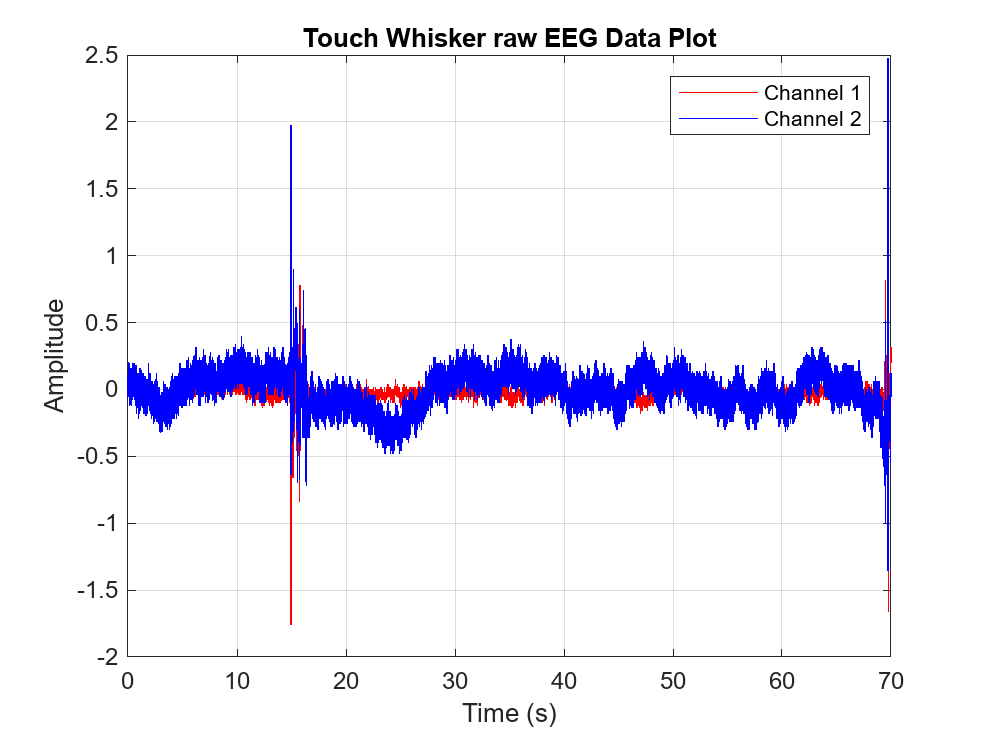


time = whisker_data.Source; 
channel1 = whisker_data.CH1; 
channel2 = whisker_data.CH2; 

figure;
plot(time, channel1, 'r', 'DisplayName', 'Channel 1'); 
hold on; 
plot(time, channel2, 'b', 'DisplayName', 'Channel 2'); 
hold off;

xlabel('Time (s)');
ylabel('Amplitude');
title('Touch Whisker raw EEG Data Plot');
legend show;
grid on;

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\akatikhaneni\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.5 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.04' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "erplab" v10.04 (see 


raw_data = table2array(whisker_data(:, 2:end));

time = whisker_data.Source; 

eeglab;


fs = 1000; 

EEG = pop_importdata('setname', 'New Raw EEG Data', ...
                     'data', raw_data', ...         
                     'srate', fs, ...              
                     'nbchan', size(raw_data, 2), ... 
                     'xmin', time(1));             

eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (70000) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



chan_labels = {'CH1', 'CH2'};
for i = 1:length(chan_labels)
    EEG.chanlocs(i).labels = chan_labels{i};
end

pop_saveset(EEG, 'filename', 'csv10_raw_eeg.set', 'filepath', './');

Saving dataset...


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


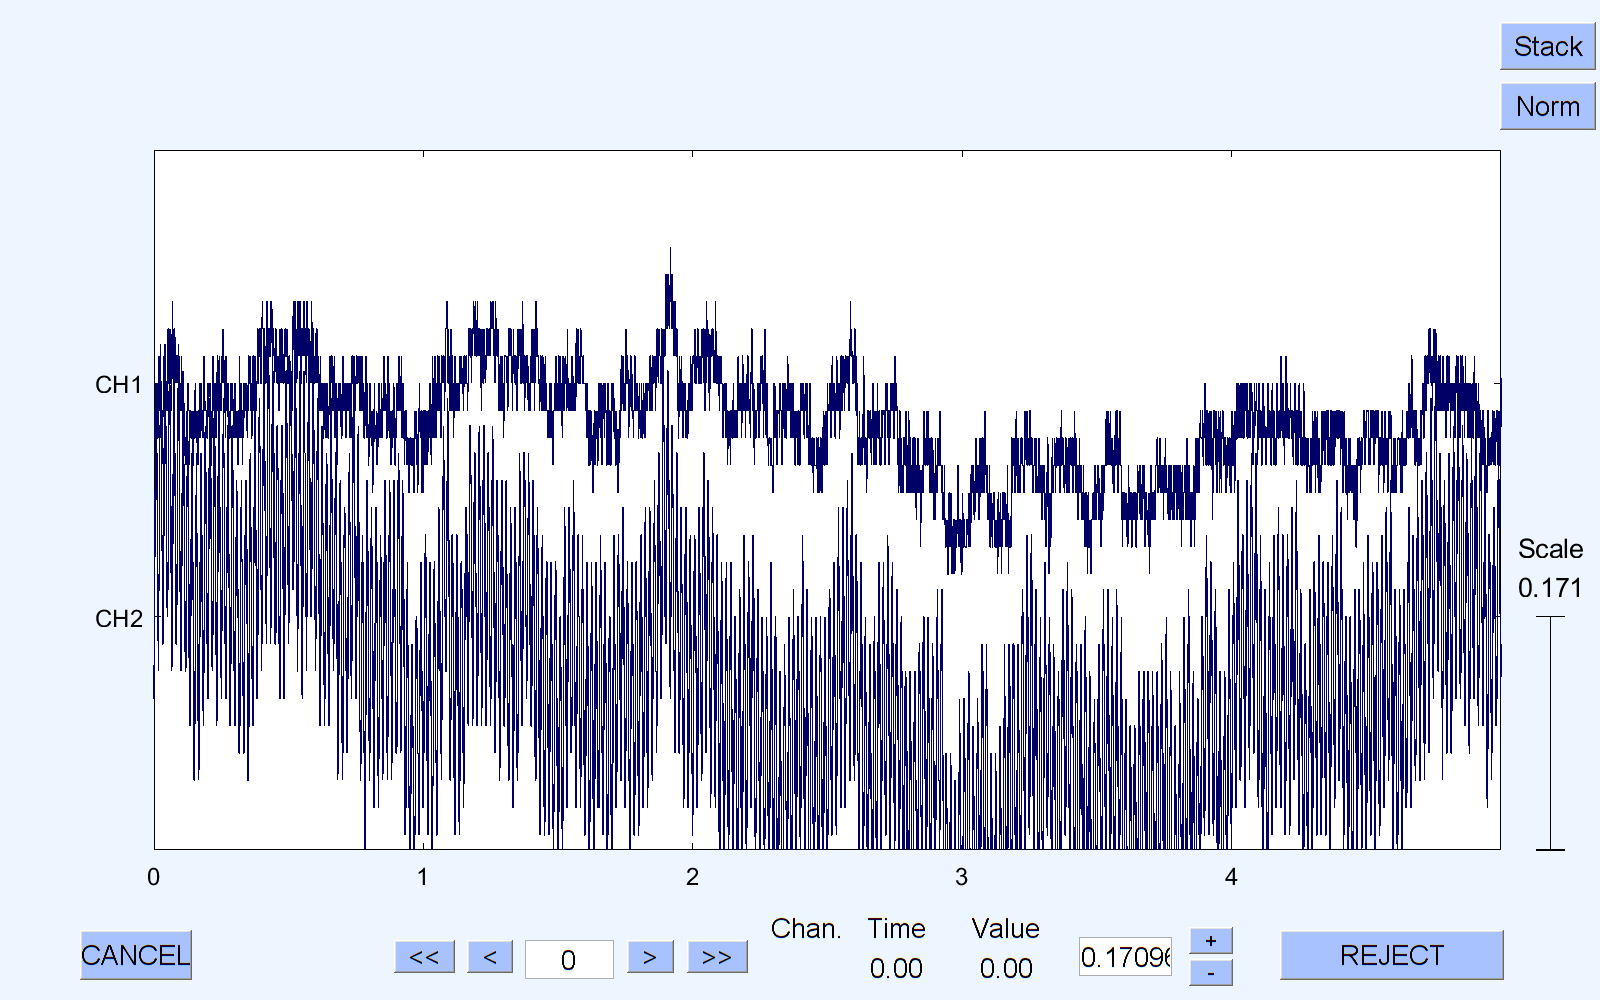


pop_eegplot(EEG);

no_stim2_data = readtable("csv_files\SDS00012.csv")

no_stim2_data = 70000×3 table
    Source     CH1      CH2 
    ______    _____    _____

        0     -0.06     -0.6
    0.001     -0.08    -0.62
    0.002      -0.1    -0.66
    0.003     -0.08     -0.7
    0.004      -0.1     -0.7
    0.005      -0.1    -0.76
    0.006     -0.08    -0.76
    0.007     -0.08    -0.74
    0.008     -0.06    -0.72
    0.009     -0.06     -0.7
     0.01     -0.08    -0.66
    0.011     -0.08    -0.62
    0.012     -0.06    -0.58
    0.013     -0.06    -0.58
    0.014     -0.06    -0.56
    0.015     -0.06    -0.56



no_stim2_data

no_stim2_data = 70000×3 table
    Source     CH1      CH2 
    ______    _____    _____

        0     -0.06     -0.6
    0.001     -0.08    -0.62
    0.002      -0.1    -0.66
    0.003     -0.08     -0.7
    0.004      -0.1     -0.7
    0.005      -0.1    -0.76
    0.006     -0.08    -0.76
    0.007     -0.08    -0.74
    0.008     -0.06    -0.72
    0.009     -0.06     -0.7
     0.01     -0.08    -0.66
    0.011     -0.08    -0.62
    0.012     -0.06    -0.58
    0.013     -0.06    -0.58
    0.014     -0.06    -0.56
    0.015     -0.06    -0.56


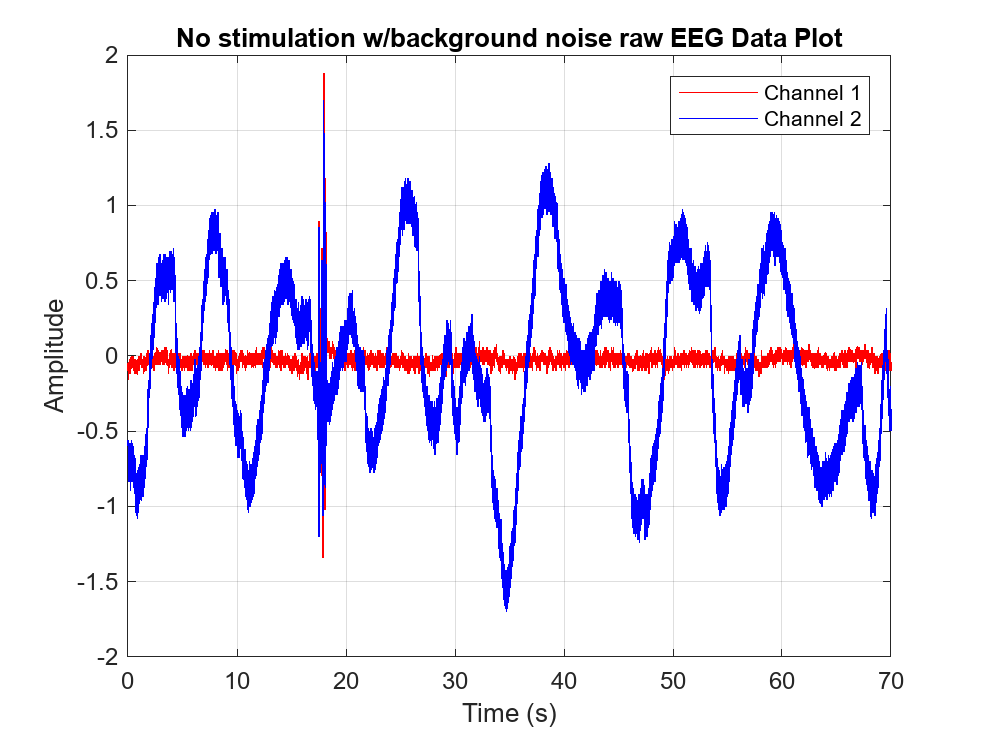


time = no_stim2_data.Source;
channel1 = no_stim2_data.CH1;
channel2 = no_stim2_data.CH2;

figure;
plot(time, channel1, 'r', 'DisplayName', 'Channel 1');
hold on;
plot(time, channel2, 'b', 'DisplayName', 'Channel 2');
hold off;

xlabel('Time (s)');
ylabel('Amplitude');
title('No stimulation w/background noise raw EEG Data Plot');
legend show;
grid on;


raw_data = table2array(no_stim2_data(:, 2:end));

time = no_stim2_data.Source;

eeglab;

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\akatikhaneni\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.5 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.04' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "erplab" v10.04 (see 


fs = 1000;

EEG = pop_importdata('setname', 'Csv12 Raw EEG Data', ...
                     'data', raw_data', ... 
                     'srate', fs, ... 
                     'nbchan', size(raw_data, 2), ... 
                     'xmin', time(1));

eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (70000) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



chan_labels = {'CH1', 'CH2'};
for i = 1:length(chan_labels)
    EEG.chanlocs(i).labels = chan_labels{i};
end

pop_saveset(EEG, 'filename', 'csv_12_raw_eeg.set', 'filepath', './');

Saving dataset...


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


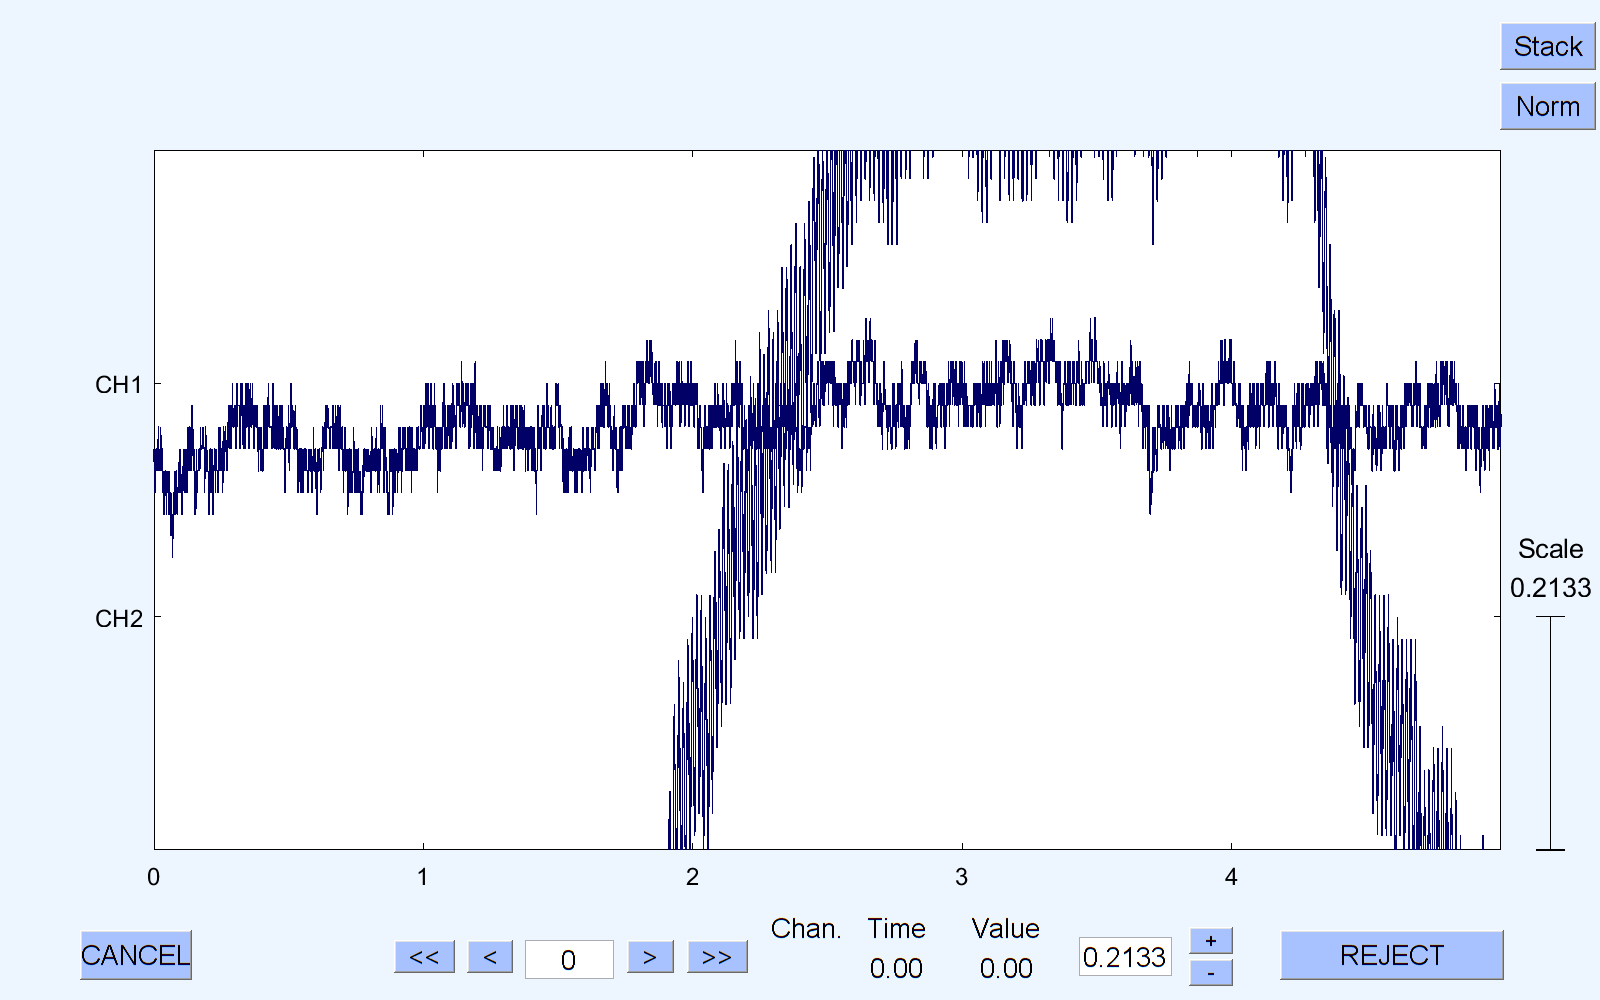


pop_eegplot(EEG);

no_stimulation3_data = readtable("M:\Documents\MATLAB\csv_files\SDS00013.csv")

no_stimulation3_data = 70000×3 table
    Source     CH1     CH2 
    ______    _____    ____

        0     -0.02     0.5
    0.001     -0.02    0.48
    0.002     -0.02    0.46
    0.003         0    0.44
    0.004     -0.02     0.4
    0.005     -0.02    0.38
    0.006         0    0.38
    0.007     -0.02    0.34
    0.008         0    0.34
    0.009         0    0.34
     0.01      0.02    0.34
    0.011         0     0.4
    0.012         0    0.42
    0.013         0    0.46
    0.014      0.02     0.5
    0.015      0.02    0.52


no_stimulation3_data

no_stimulation3_data = 70000×3 table
    Source     CH1     CH2 
    ______    _____    ____

        0     -0.02     0.5
    0.001     -0.02    0.48
    0.002     -0.02    0.46
    0.003         0    0.44
    0.004     -0.02     0.4
    0.005     -0.02    0.38
    0.006         0    0.38
    0.007     -0.02    0.34
    0.008         0    0.34
    0.009         0    0.34
     0.01      0.02    0.34
    0.011         0     0.4
    0.012         0    0.42
    0.013         0    0.46
    0.014      0.02     0.5
    0.015      0.02    0.52


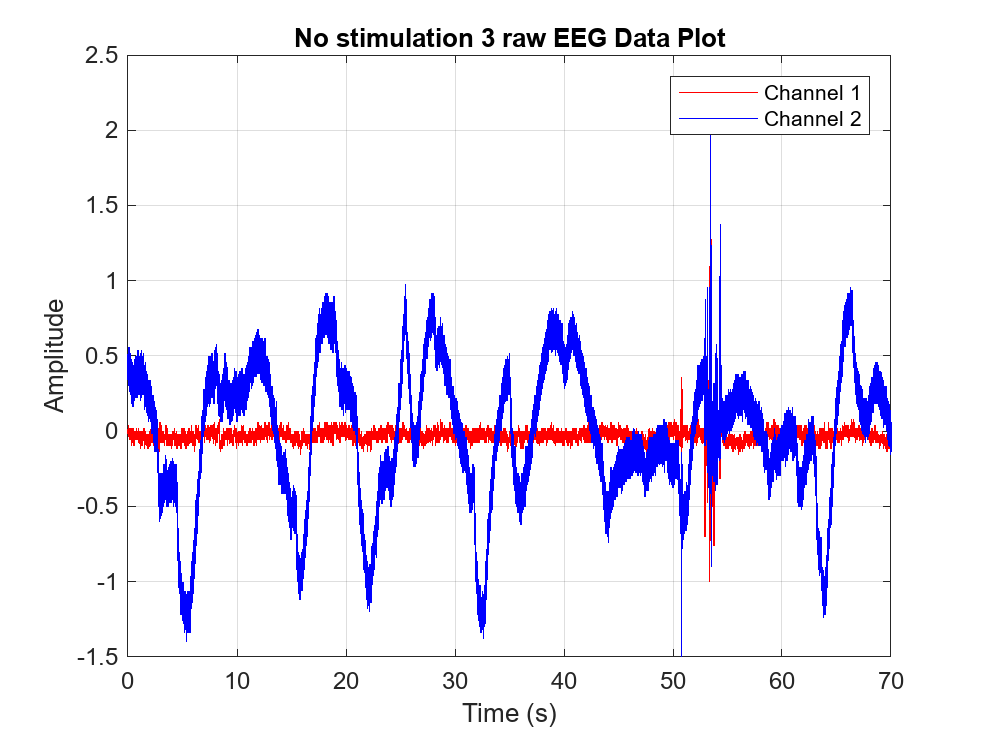


time = no_stimulation3_data.Source;
channel1 = no_stimulation3_data.CH1;
channel2 = no_stimulation3_data.CH2;

figure;
plot(time, channel1, 'r', 'DisplayName', 'Channel 1');
hold on;
plot(time, channel2, 'b', 'DisplayName', 'Channel 2');
hold off;

xlabel('Time (s)');
ylabel('Amplitude');
title('No stimulation 3 raw EEG Data Plot');
legend show;
grid on;


raw_data = table2array(no_stimulation3_data(:, 2:end));

time = no_stimulation3_data.Source;

eeglab;

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\akatikhaneni\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.5 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.04' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "erplab" v10.04 (see >> help eegplugin_erplab) - new version 12.00 available
EEGLAB: addin


fs = 1000;

EEG = pop_importdata('setname', 'Csv13 Raw EEG Data', ... 
                     'data', raw_data', ...
                     'srate', fs, ...
                     'nbchan', size(raw_data, 2), ... 
                     'xmin', time(1));

eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (70000) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



chan_labels = {'CH1', 'CH2'};
for i = 1:length(chan_labels)
    EEG.chanlocs(i).labels = chan_labels{i};
end

pop_saveset(EEG, 'filename', 'csv_13_raw_eeg.set', 'filepath', './');

Saving dataset...



pop_eegplot(EEG);

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


touch_foot_data = readtable('M:/Documents/MATLAB/csv_files/SDS00014.csv')

touch_foot_data = 70000×3 table
    Source     CH1     CH2 
    ______    _____    ____

        0     -0.02    0.28
    0.001     -0.02    0.24
    0.002     -0.04    0.22
    0.003     -0.04    0.18
    0.004     -0.04    0.14
    0.005     -0.04    0.12
    0.006     -0.04     0.1
    0.007     -0.06    0.08
    0.008     -0.02     0.1
    0.009     -0.04    0.14
     0.01     -0.02    0.14
    0.011         0     0.2
    0.012     -0.04    0.26
    0.013     -0.02    0.28
    0.014      0.02    0.32
    0.015     -0.02    0.34


touch_foot_data

touch_foot_data = 70000×3 table
    Source     CH1     CH2 
    ______    _____    ____

        0     -0.02    0.28
    0.001     -0.02    0.24
    0.002     -0.04    0.22
    0.003     -0.04    0.18
    0.004     -0.04    0.14
    0.005     -0.04    0.12
    0.006     -0.04     0.1
    0.007     -0.06    0.08
    0.008     -0.02     0.1
    0.009     -0.04    0.14
     0.01     -0.02    0.14
    0.011         0     0.2
    0.012     -0.04    0.26
    0.013     -0.02    0.28
    0.014      0.02    0.32
    0.015     -0.02    0.34


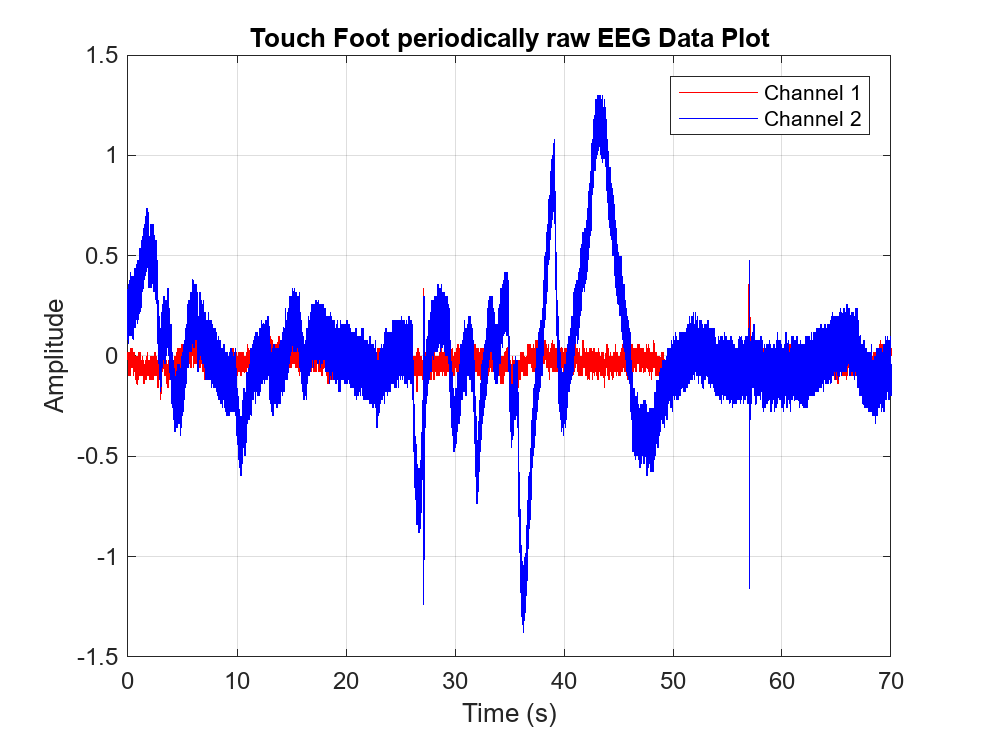


time = touch_foot_data.Source;
channel1 = touch_foot_data.CH1;
channel2 = touch_foot_data.CH2;

figure;
plot(time, channel1, 'r', 'DisplayName', 'Channel 1');
hold on;
plot(time, channel2, 'b', 'DisplayName', 'Channel 2');
hold off;

xlabel('Time (s)');
ylabel('Amplitude');
title('Touch Foot periodically raw EEG Data Plot');
legend show;
grid on;

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\akatikhaneni\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.5 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.04' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "erplab" v10.04 (see >> help eegplugin_erplab) - new version 12.00 available
EEGLAB: addin


raw_data = table2array(touch_foot_data(:, 2:end));

time = touch_foot_data.Source;

eeglab;


fs = 1000;

EEG = pop_importdata('setname', 'Csv 14 Raw EEG Data', ... 
                     'data', raw_data', ...
                     'srate', fs, ...
                     'nbchan', size(raw_data, 2), ... 
                     'xmin', time(1));

eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (70000) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



chan_labels = {'CH1', 'CH2'};
for i = 1:length(chan_labels)
    EEG.chanlocs(i).labels = chan_labels{i};
end

pop_saveset(EEG, 'filename', 'csv_14_raw_eeg.set', 'filepath', './');

Saving dataset...



pop_eegplot(EEG);

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\akatikhaneni\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.5 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.04' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "erplab" v10.04 (see 

eeglab; 


EEG1 = pop_loadset('filename', 'csv8_fully_filtered.set', 'filepath', './');

pop_loadset(): loading file .\csv8_fully_filtered.set ...


Reading float file '.\csv8_fully_filtered.fdt'...
Scaling components to RMS microvolt


EEG2 = pop_loadset('filename', 'csv14_filtered.set', 'filepath', './');

pop_loadset(): loading file .\csv14_filtered.set ...
Reading float file '.\csv14_filtered.fdt'...
Scaling components to RMS microvolt


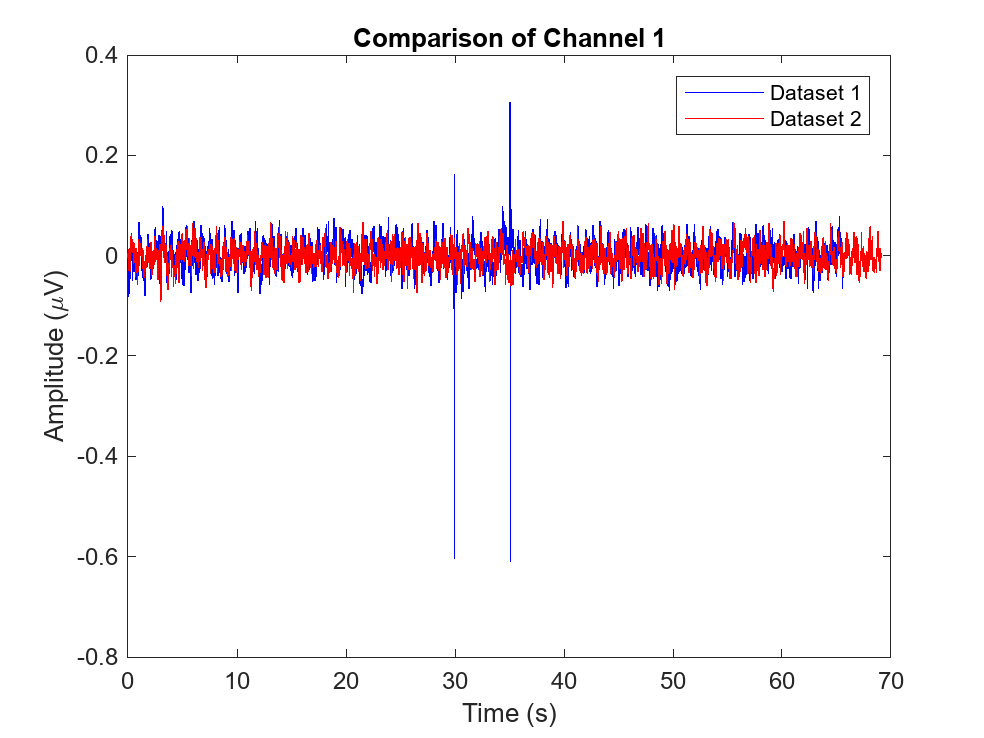


if EEG1.srate ~= EEG2.srate
    error('Sampling rates of the datasets do not match. Resample them to the same rate before comparison.');
end

if EEG1.nbchan ~= EEG2.nbchan
    error('The number of channels in the datasets does not match. Ensure both datasets have the same channel configuration.');
end

channel = 1;
time_vector1 = linspace(0, EEG1.pnts / EEG1.srate, EEG1.pnts); 
time_vector2 = linspace(0, EEG2.pnts / EEG2.srate, EEG2.pnts); 

figure;
plot(time_vector1, EEG1.data(channel, :), 'b', 'DisplayName', 'Dataset 1'); 
hold on;


plot(time_vector2, EEG2.data(channel, :), 'r', 'DisplayName', 'Dataset 2'); 
hold off;

xlabel('Time (s)');
ylabel('Amplitude (\muV)');
legend('show');
title(['Comparison of Channel ', num2str(channel)]);